# Classify Text Data Using BERT

This example shows how to classify text data using a pretrained BERT model as a feature extractor.

The simplest use of a pretrained BERT model is to use it as a feature extractor. In particular, you can use the BERT model to convert documents to feature vectors which you can then use as input to train a deep learning classification network.

This example shows how to use a pretrained BERT model to classify failure events given a data set of factory reports.

## Load Pretrained BERT Model

Load a pretrained BERT model using the `bert` function. The model consists of a tokenizer that encodes text as sequences of integers, and a structure of parameters.

mdl = bert

mdl = 包含以下字段的 struct :
     Tokenizer: [1×1 bert.tokenizer.BERTTokenizer]
    Parameters: [1×1 struct]


View the BERT model tokenizer. The tokenizer encodes text as sequences of integers and holds the details of padding, start, separator and mask tokens.

tokenizer = mdl.Tokenizer

tokenizer =   BERTTokenizer - 属性:

      PaddingToken: "[PAD]"
        StartToken: "[CLS]"
    SeparatorToken: "[SEP]"
         MaskToken: "[MASK]"
     FullTokenizer: [1×1 bert.tokenizer.internal.FullTokenizer]
       PaddingCode: 1
     SeparatorCode: 103
         StartCode: 102
          MaskCode: 104


## 1.Load Data

Load the example data. The file `factoryReports.csv` contains factory reports, including a text description and categorical labels for each event.

filename = "E:\Dataset\school image\final data\JNU_annotation3.csv";
data = readtable(filename,"TextType","string");
head(data)

ans = 8×2 table
                                                       id                                                                                                     annotation                                             
    _________________________________________________________________________________________________________    ____________________________________________________________________________________________________

    "E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\1.jpg"       "a bridge crosses a river with a city in the background with trees in the background and a group"   
    "E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\10.jpg"      "a view of a river with a boat in the background with trees in the background and trees in"         
    "E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\100.jpg"     "a group of pe

The goal of this example is to classify events by the label in the `Category` column. To divide the data into classes, convert these labels to categorical.

data.Category = categorical(data.label);

View the number of classes.

classes = categories(data.Category);
numClasses = numel(classes)

numClasses = 3

View the distribution of the classes in the data using a histogram.

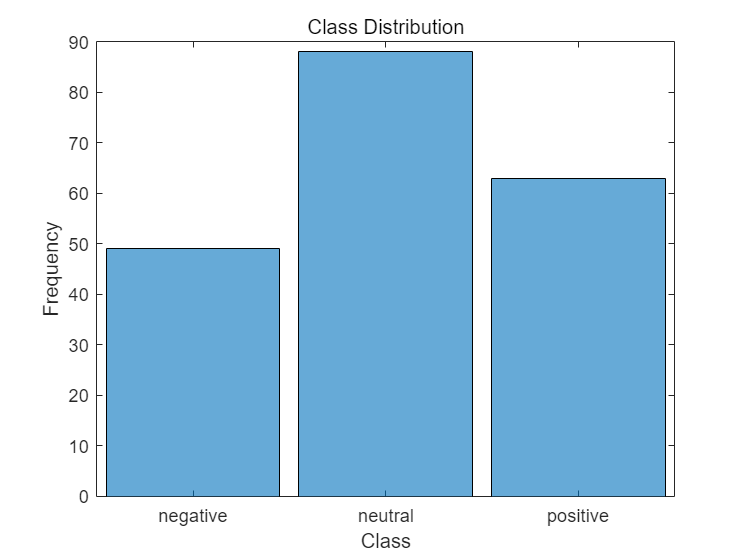

figure
histogram(data.Category);
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

Encode the text data using the BERT model tokenizer using the `encode` function and add the tokens to the training data table.

## 2.对annotation进行encode

data.Tokens = encode(tokenizer, data.annotation);

The next step is to partition it into sets for training and validation. Partition the data into a training partition and a held-out partition for validation and testing. Specify the holdout percentage to be 20%.

cvp = cvpartition(data.Category,"Holdout",0.1);
dataTrain = data(training(cvp),:);
dataValidation = data(test(cvp),:);

View the number of training and validation observations.

numObservationsTrain = size(dataTrain,1)

numObservationsTrain = 180

numObservationsValidation = size(dataValidation,1)

numObservationsValidation = 20

Extract the text data, labels, and encoded BERT tokens from the partitioned tables.

textDataTrain = dataTrain.annotation;
textDataValidation = dataValidation.annotation;

TTrain = dataTrain.Category;
TValidation = dataValidation.Category;

tokensTrain = dataTrain.Tokens;
tokensValidation = dataValidation.Tokens;

To check that you have imported the data correctly, visualize the training text data using a word cloud.

figure
wordcloud(textDataTrain);
title("Training Data")

View the BERT token codes of the first few training documents.

## 3.将数据转化为train目录

tokensTrain = data.Tokens;

tokensTrain{1:5}

ans =          102        1038        2959        7822        1038        2315        2008        1038        2104        2000        1997        4282        2008        3629        2000        1997        4282        1999        1038        2178         103


ans =          102        1038        3194        1998        1038        2315        2008        1038        4050        2000        1997        4282        2008        3629        2000        1997        4282        1999        3629        2000         103


ans =          102        1038        2178        1998        2112        3062        2000        2393        1998        1038        2313        2304        1998        2301        2008       12978        2016        2000        1997        4282        2007         103


ans =          102        1038        2315        2008        1038        2844        1998        3629        1999        1038        5120        2007        1997        2218        1998        1997        2347        2008        3629        2000         103


ans =          102        1038        2178        1998        2112        5560        8302        2016        2007        2328        1998        1038        4587        3140        3225         103


## Prepare Data for Training

Convert the documents to feature vectors using the BERT model as a feature extractor.

% To extract the features of the training data by iterating over
% mini-batches, create a |minibatchqueue| object.

% Mini-batch queues require a single datastore that outputs both the
% predictors and responses. Create array datastores containing the training
% BERT tokens and labels and combine them using the |combine| function.
dsXTrain = arrayDatastore(tokensTrain,"OutputType","same");
dsTTrain = arrayDatastore(TTrain);
cdsTrain = combine(dsXTrain,dsTTrain);

% Create a combined datastore for the validation data using the same steps.
dsXValidation = arrayDatastore(tokensValidation,"OutputType","same");
dsTValidation = arrayDatastore(TValidation);
cdsValidation = combine(dsXValidation,dsTValidation);

Create a mini-batch queue for the training data. Specify a mini-batch size of 32 and preprocess the mini-batches using the `preprocessPredictors` function, listed at the end of the example.

## 4.将数据以array的形式储存

cdsTrain = arrayDatastore(tokensTrain,"OutputType","same");

miniBatchSize = 32;
paddingValue = mdl.Tokenizer.PaddingCode;
maxSequenceLength = mdl.Parameters.Hyperparameters.NumContext;

mbqTrain = minibatchqueue(cdsTrain,1,...
    "MiniBatchSize",miniBatchSize, ...
    "MiniBatchFcn",@(X) preprocessPredictors(X,paddingValue,maxSequenceLength));

Create a mini-batch queue for the validation data using the same steps.

mbqValidation = minibatchqueue(cdsValidation,1,...
    "MiniBatchSize",miniBatchSize, ...
    "MiniBatchFcn",@(X) preprocessPredictors(X,paddingValue,maxSequenceLength));

To speed up feature extraction. Convert the BERT model weights to gpuArray if a GPU is available.

if canUseGPU
    mdl.Parameters.Weights = dlupdate(@gpuArray,mdl.Parameters.Weights);
end

Convert the training sequences of BERT model tokens to a `N`-by-|embeddingDimension| array of feature vectors, where `N` is the number of training observations and `embeddingDimension` is the dimension of the BERT embedding.

## 5.词向量embedding

featuresTrain = [];
reset(mbqTrain);
while hasdata(mbqTrain)
    X = next(mbqTrain);
    features = bertEmbed(X,mdl.Parameters);
    featuresTrain = [featuresTrain gather(extractdata(features))];
end

Transpose the training data to have size `N`-by-|embeddingDimension|.

featuresTrain = featuresTrain.';

Convert the validation data to feature vectors using the same steps.

featuresValidation = [];

reset(mbqValidation);
while hasdata(mbqValidation)
    X = next(mbqValidation);
    features = bertEmbed(X,mdl.Parameters);
    featuresValidation = cat(2,featuresValidation,gather(extractdata(features)));
end
featuresValidation = featuresValidation.';

% featuresValidation

## annotation特征提取（BERT embedding）

annotation_features = [featuresTrain]

annotation_features = 1112×768 single 矩阵
   -0.2816   -0.0857   -0.4064    0.1527   -0.1369    0.1509    0.2115    0.5470   -0.4881   -0.3776   -0.3879   -0.4753   -0.2018    0.5798    0.6408    0.0031   -0.2914    0.7873    0.2473   -0.3592    0.0419   -0.3633   -0.0706   -0.5499    0.0753   -0.2244    0.1759    0.1121    0.2317    0.1303    0.0686    0.2481   -0.5359   -0.5408    0.8174   -0.3381    0.2685   -0.2268    0.1118    0.0512   -0.0292    0.0998    0.0917   -0.3782    0.2045   -0.9527   -2.3029    0.0683   -0.3902    0.0048
   -0.9692   -0.6293   -0.6847    0.1079   -0.0135    0.2046   -0.0649    0.8410   -0.5205   -0.4298   -0.2801   -0.5006   -0.4211    0.2175    0.1949   -0.1212   -0.2693    0.6700    0.1005   -0.2166    0.3164   -0.3369   -0.2753   -0.2691    0.4475   -0.3673    0.5778   -0.0345    0.2428    0.4148   -0.1461    0.0726   -0.1950   -0.6171    0.6421   -0.6140    0.2926   -0.1677   -0.5766    0.1017   -0.3303    0.1137    0.7042   -0.2412   -0.0610   -0.75

% writematrix(annotation_features, 'features_annotation.csv')

## TSNE降维&HDBSCAN聚类

XY = tsne(annotation_features,'Algorithm','Exact','Distance','cosine','NumPCAComponents',50);

XYZ = tsne(annotation_features,'Algorithm','Exact','Distance','cosine','NumPCAComponents',50,'NumDimensions',3);

XYZ

XYZ = 1112×3 single 矩阵
   -9.5974   27.6932  -44.9786
    3.6735   35.6742  -26.9023
    3.2015   10.7496  -33.2440
    2.6735    6.4274   -9.5631
   11.8242  -20.1300   41.5210
   -8.1515  -22.9601    6.3554
    0.9883  -27.4923   30.8616
   41.8921    1.2036    3.4133
   10.0289   15.5591  -35.2356
    8.8454   20.7984  -44.7497


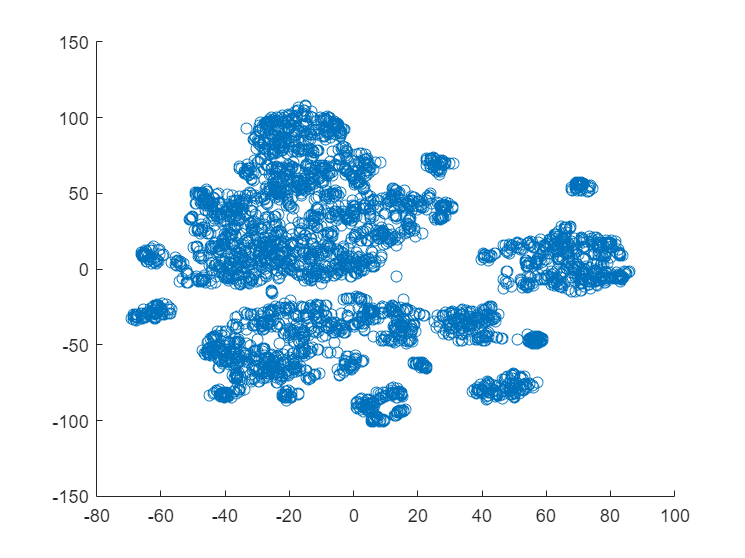

% 绘制散点图，二维
scatter(XY(:,1),XY(:,2))  

% 绘制三维散点图
%scatter3(XYZ(:,1),XYZ(:,2),XYZ(:,3))

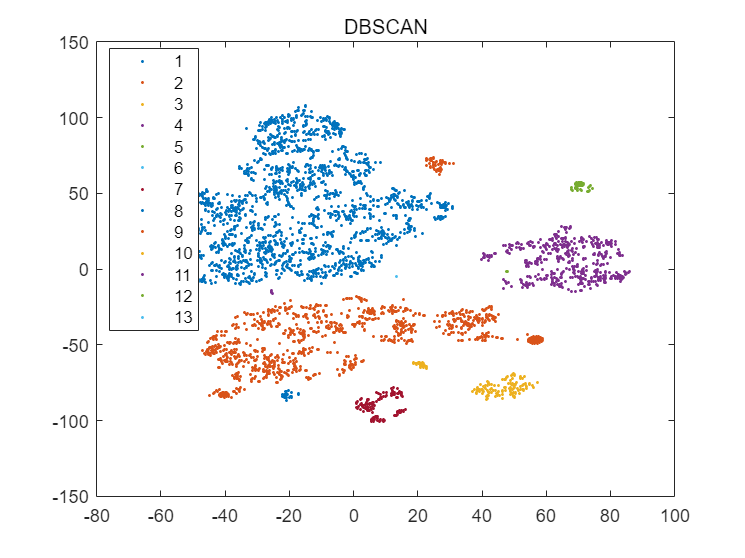

% HDBSCAN聚类（无监督自动聚类）
cidx = dbscan(XY,5,1,'Distance','chebychev');
gscatter(XY(:,1),XY(:,2),cidx);
title( 'DBSCAN' )

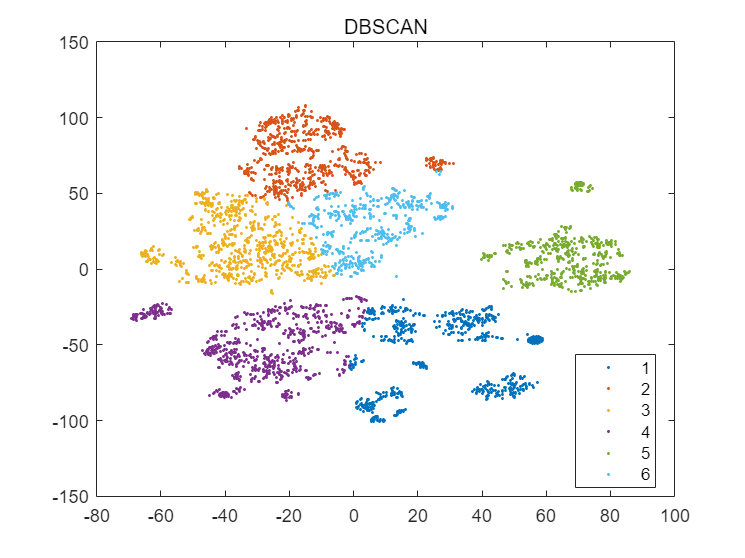

% kmeans聚类（设置聚类数量）
cidx = kmeans(XY,6);
% 绘制聚类后散点图
gscatter(XY(:,1),XY(:,2),cidx);
title( 'DBSCAN' )

% 绘制聚类后散点图,三维
% scatter3(XYZ(:,1),XYZ(:,2),XYZ(:,3),10,cidx,'filled');
% % (Y3(:,1),Y3(:,2),Y3(:,3),,clr(L+1,:),'filled')
% title( 'DBSCAN' )

## Define Deep Learning Network

Define a deep learning network that classifies the feature vectors.

numFeatures = mdl.Parameters.Hyperparameters.HiddenSize;
layers = [
    featureInputLayer(numFeatures)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

## Specify Training Options

Specify the training options using the `trainingOptions` function. * Train with a mini-batch size of 64. * Shuffle the data every epoch. * Validate the network using the validation data. * Display the training progress in a plot and suppress the verbose output.

opts = trainingOptions('adam',...
    "MaxEpoch",1000,...
    "MiniBatchSize",64,...
    "ValidationData",{featuresValidation,dataValidation.Category},...
    "Shuffle","every-epoch", ...
    "Plots","training-progress", ...
    "Verbose",0);

## Train Network

Train the network using the `trainNetwork` function.

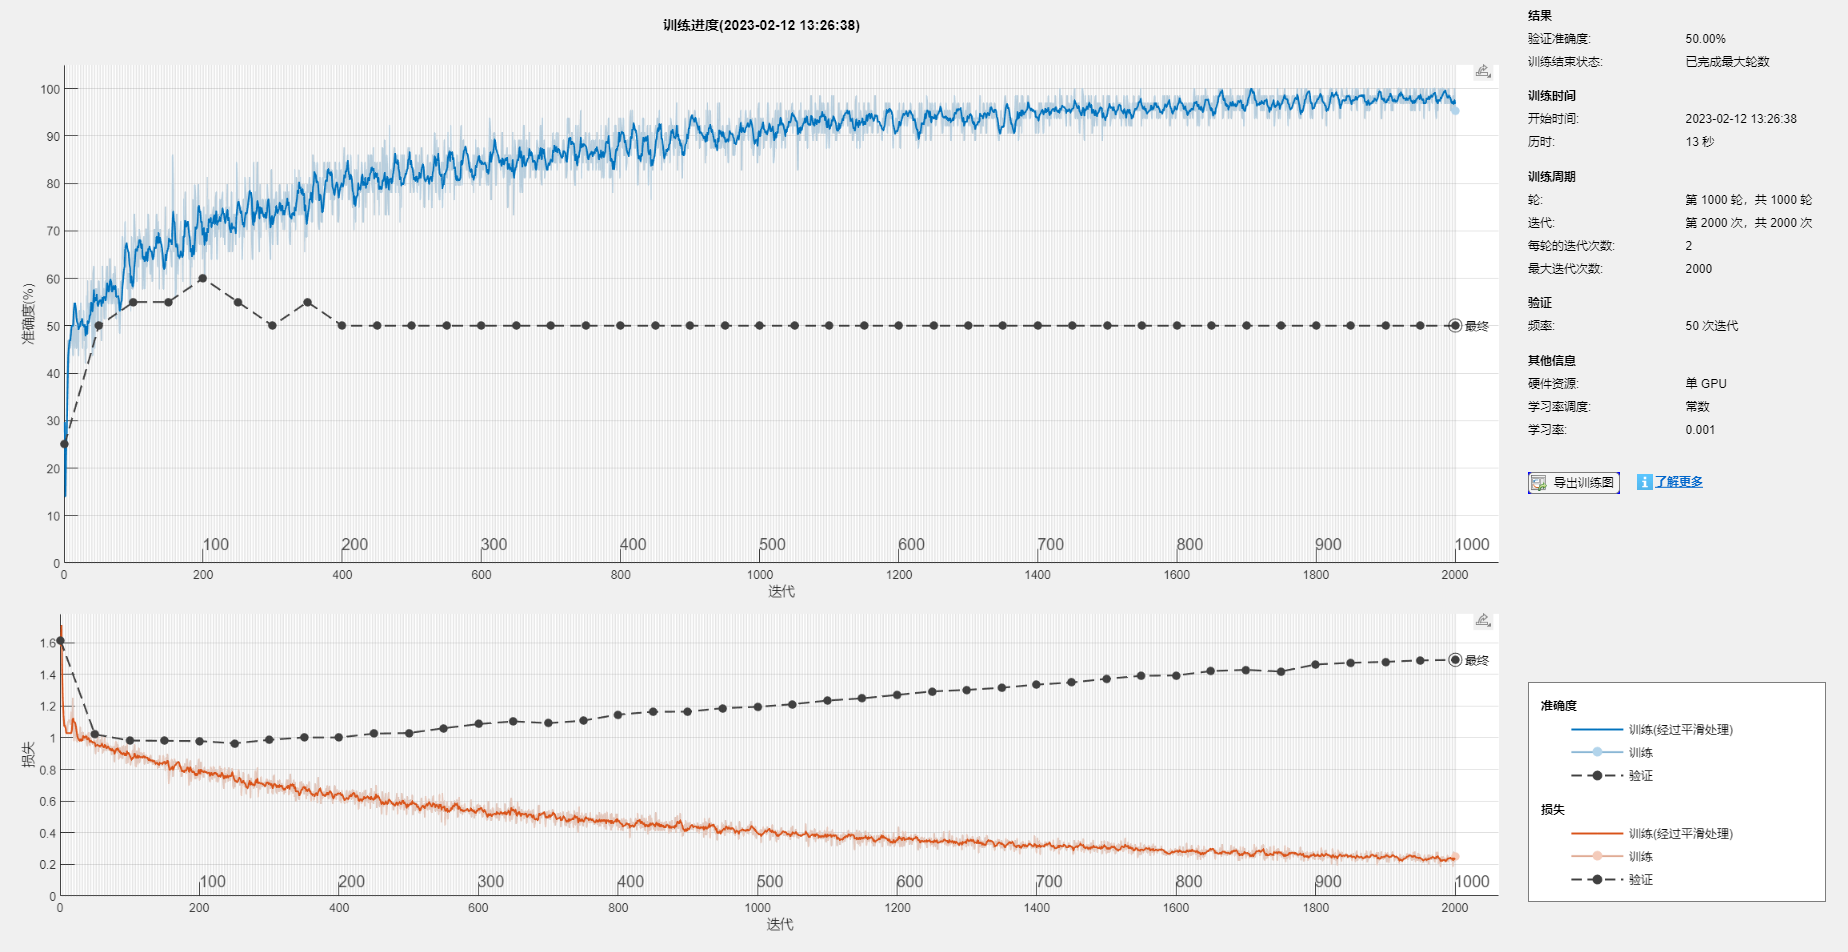

net = trainNetwork(featuresTrain,dataTrain.Category,layers,opts);

net

## Test Network

Make predictions using the validation data and display the results in a confusion matrix.

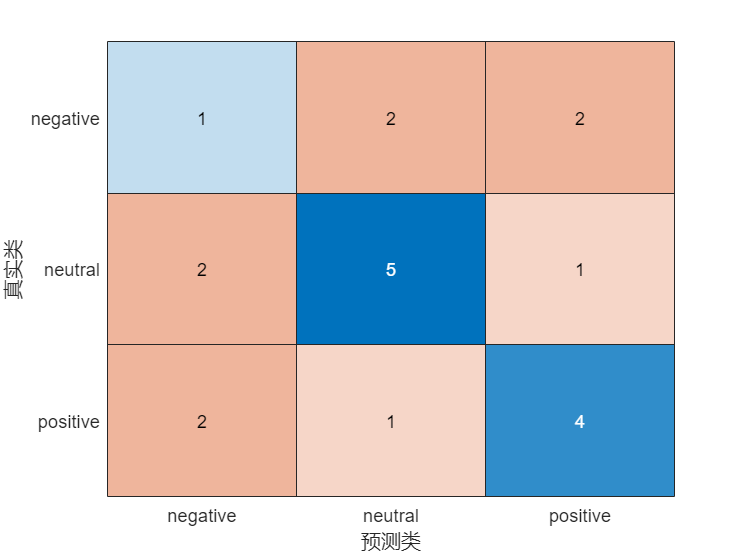

YPredValidation = classify(net,featuresValidation);

figure
confusionchart(TValidation,YPredValidation)

Calculate the validation accuracy.

accuracy = mean(dataValidation.Category == YPredValidation)

accuracy = 0.5000

## Predict Using New Data

Classify the event type of three new reports. Create a string array containing the new reports.

reportsNew = [ ...
    "Coolant is pooling underneath sorter."
    "Sorter blows fuses at start up."
    "There are some very loud rattling sounds coming from the assembler."];

filename = "E:\Dataset\school image\final data\JNU_annotation.csv";
data = readtable(filename,"TextType","string");
head(data)

ans = 8×2 table
                                                     id                                                                                               annotation                                          
    _____________________________________________________________________________________________________    _____________________________________________________________________________________________

    "E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_images\JNU\1000_1.jpg"    "a bench sitting in the middle of a field with trees in the distance behind him and a bird"  
    "E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_images\JNU\1000_2.jpg"    "a couple of cars driving down a street"                                                     
    "E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_images\JNU\1000_3.jpg"    "a car parked on the side of a road with a kite in the back gr

Tokenize the text data using the same steps as the training documents.

tokensNew = encode(tokenizer,data.annotation);

Pad the sequences of tokens to the same length using the `padsequences` function and pad using the tokenizer padding code.

XNew = padsequences(tokensNew,2,"PaddingValue",tokenizer.PaddingCode);

featuresNew = bertEmbed(XNew,mdl.Parameters)'

错误使用  * 
Out of memory on device. To view more detail about available memory on the GPU, use 'gpuDevice()'. If the problem persists, reset the GPU by calling 'gpuDevice(1)'.

出错  *  (第 70 行)
    ydata = xdata * ydata;

出错 transformer.layer.gelu (第 13 行)
Z = 0.5*X.*( 1 + tanh( sqrt(2/pi)*(X+0.044715*(X.^3)) ) );

出错 <a h

featuresNew = gather(extractdata(featuresNew));

Classify the new sequences using the trained model.

featuresNew = bertEmbed(XNew,mdl.Parameters)';
featuresNew = gather(extractdata(featuresNew));
labelsNew = classify(net,featuresNew)

labelsNew = 3×1 categorical 数组
     positive 
     neutral 
     neutral 


## Supporting Functions

## Predictors Preprocessing Functions

The `preprocessPredictors` function truncates the mini-batches to have the specified maximum sequence length, pads the sequences to have the same length. Use this preprocessing function to preprocess the predictors only.

function X = preprocessPredictors(X,paddingValue,maxSeqLen)

X = truncateSequences(X,maxSeqLen);
X = padsequences(X,2,"PaddingValue",paddingValue);

end

## BERT Embedding Function

The `bertEmbed` function maps input data to embedding vectors and optionally applies dropout using the "DropoutProbability" name-value pair.

function Y = bertEmbed(X,parameters,args)

arguments
    X
    parameters
    args.DropoutProbability = 0
end

dropoutProbabilitiy = args.DropoutProbability;

Y = bert.model(X,parameters, ...
    "DropoutProb",dropoutProbabilitiy, ...
    "AttentionDropoutProb",dropoutProbabilitiy);

% To return single feature vectors, return the first element.
Y = Y(:,1,:);
Y = squeeze(Y);

end